# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 50;
KiStatic = 1000;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 0;
megaSweep = 1;  
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# Setting up gains for sweep

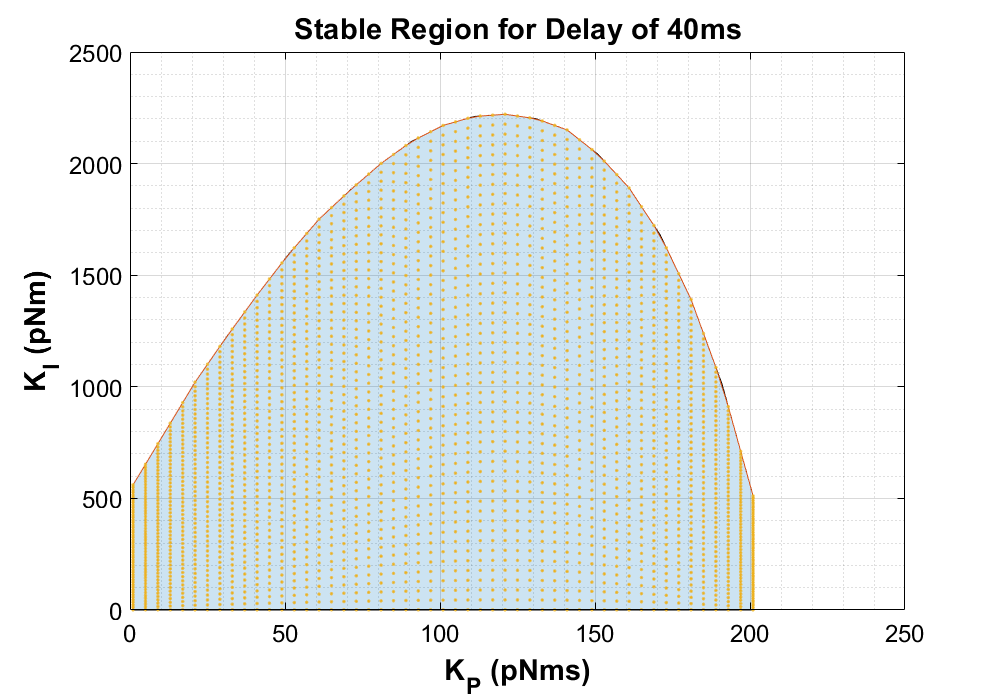

%Smooth Stability Data - Get max 04 Slice for sweeping over stable domain

slicePath = strcat(commonPath,'\Stability Sweep Data\');
latestSlice = latestTimeParse(slicePath,'04DelaySlice');
load(latestSlice)
clear slicePath latestSlice
xdata = stableSliceMax(:,1);
ydata = stableSliceMax(:,2);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
a = area(xdata,ydata);
hold on
a.FaceAlpha = 0.2;
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('K_P (pNms)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I (pNm)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title('Stable Region for Delay of 40ms','FontName','Helvetica','FontSize',22,'FontWeight','bold')
grid on
grid minor
xlim([0 250])
ylim([0 2500])

%Build Stable sampling region for Ki, Kp
Kpsize = 51;
Kisize = 51;
stableSweepKp = linspace(min(xdata),max(xdata),Kpsize);
maxKiInterp = interp1(xdata,ydata,stableSweepKp);
plot(stableSweepKp,maxKiInterp)

stableSweepKi = zeros(length(stableSweepKp),Kisize);
orderedPairs = zeros(Kpsize*Kisize,2);
opIndex = 1;
%Build Ki regions
for i = 1:length(stableSweepKp)
    stableSweepKi(i,:) = linspace(1,maxKiInterp(i),Kisize);
    orderedPairs(opIndex:opIndex - 1 + Kisize,1) = stableSweepKp(i)*ones(Kisize,1);
    orderedPairs(opIndex:opIndex - 1 + Kisize,2) = stableSweepKi(i,:)';
    opIndex = opIndex + Kisize;
end

plot(orderedPairs(:,1),orderedPairs(:,2),'.')


%Full region sweep
KpFull = linspace(1,501,Kpsize); %pNms
KiFull = linspace(1,3001,Kisize); %pNm        
KiFull = repmat(KiFull,Kpsize,1);

%Toggle for stable region or full region
stableOnly = 1;

# Ridiculous Sweep (All params minus td = 0.04)

if megaSweep == 1  
    set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
        ,'FastRestart','on')
    save_system(simName)
    
    td = 0.04;
    [nump,denp]=padeWrap(td);
    d_tf = tf(nump,denp);
    if stableOnly == 0
        Kp = KpFull;
        Ki = KiFull;
    else
        Kp = stableSweepKp;
        Ki = stableSweepKi;
    end

    switchThresh = 0:.25:5;
    decimationFactor = 1;
    pureSinDecimate = pureSin(1:decimationFactor:end, :);
    sinfreqsDecimate = sinfreqs(1:decimationFactor:end);
    
    innerSize = length(Kp)*length(Ki)*length(switchThresh);
    tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
    
    %FFT Params
    Fs = 1/(pureSinTime(2)-pureSinTime(1));
    N = 10000;   
    
    
    emptyarray = -1000*ones(1,length(pureSinTime));
    hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
        'hError',-1,'hFitSAE',-1,'hSAE',-1),1,length(switchThresh));
    fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,...
        'hybridInfo',hybridStruct);
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
    emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));
    
    remaining = length(Kp)*size(Ki,2);
    for i = 1:length(Kp)
        for j = 1:size(Ki,2)
            tic
            sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(i,j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
                emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
            
            toc
            remaining = remaining-1
        end
        
        basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
        savePath = genFileName(basepath,strcat('megaSweep',num2str(i)));
        tic
        save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
        toc
        
        sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
        
    end
    

    
%     tic
%     [hybridOut,hFit,hGain,hPhase,hError,smoothOut,sGain,sPhase,sError] = deconstruct(sweepData);
%     toc
    

end

Elapsed time is 6.474850 seconds.


remaining = 2600

Elapsed time is 6.965599 seconds.


remaining = 2599

Elapsed time is 6.466921 seconds.


remaining = 2598

Elapsed time is 6.138218 seconds.


remaining = 2597

Elapsed time is 6.563639 seconds.


remaining = 2596

Elapsed time is 6.175318 seconds.


remaining = 2595

Elapsed time is 6.195477 seconds.


remaining = 2594

Elapsed time is 6.206854 seconds.


remaining = 2593

Elapsed time is 6.253306 seconds.


remaining = 2592

Elapsed time is 6.258574 seconds.


remaining = 2591

Elapsed time is 6.233128 seconds.


remaining = 2590

Elapsed time is 6.242760 seconds.


remaining = 2589

Elapsed time is 6.221186 seconds.


remaining = 2588

Elapsed time is 6.213209 seconds.


remaining = 2587

Elapsed time is 6.186016 seconds.


remaining = 2586

Elapsed time is 6.174071 seconds.


remaining = 2585

Elapsed time is 6.150432 seconds.


remaining = 2584

Elapsed time is 6.162744 seconds.


remaining = 2583

Elapsed time is 6.150355 seconds.


remaining = 2582

Elapsed time is 6.146401 seconds.


remaining = 2581

Elapsed time is 6.141802 seconds.


remaining = 2580

Elapsed time is 6.152727 seconds.


remaining = 2579

Elapsed time is 6.123450 seconds.


remaining = 2578

Elapsed time is 6.127311 seconds.


remaining = 2577

Elapsed time is 6.115441 seconds.


remaining = 2576

Elapsed time is 6.201185 seconds.


remaining = 2575

Elapsed time is 6.132837 seconds.


remaining = 2574

Elapsed time is 6.125773 seconds.


remaining = 2573

Elapsed time is 6.170028 seconds.


remaining = 2572

Elapsed time is 6.135397 seconds.


remaining = 2571

Elapsed time is 6.120425 seconds.


remaining = 2570

Elapsed time is 6.158646 seconds.


remaining = 2569

Elapsed time is 6.205780 seconds.


remaining = 2568

Elapsed time is 6.119302 seconds.


remaining = 2567

Elapsed time is 6.157827 seconds.


remaining = 2566

Elapsed time is 6.134225 seconds.


remaining = 2565

Elapsed time is 6.147536 seconds.


remaining = 2564

Elapsed time is 6.160511 seconds.


remaining = 2563

Elapsed time is 6.120957 seconds.


remaining = 2562

Elapsed time is 6.130208 seconds.


remaining = 2561

Elapsed time is 6.124788 seconds.


remaining = 2560

Elapsed time is 6.142696 seconds.


remaining = 2559

Elapsed time is 6.154491 seconds.


remaining = 2558

Elapsed time is 6.165609 seconds.


remaining = 2557

Elapsed time is 6.214411 seconds.


remaining = 2556

Elapsed time is 6.164021 seconds.


remaining = 2555

Elapsed time is 6.136507 seconds.


remaining = 2554

Elapsed time is 6.157206 seconds.


remaining = 2553

Elapsed time is 6.151944 seconds.


remaining = 2552

Elapsed time is 6.126010 seconds.


remaining = 2551

Elapsed time is 6.172575 seconds.


remaining = 2550

Elapsed time is 3.178949 seconds.


Elapsed time is 6.154115 seconds.


remaining = 2549

Elapsed time is 6.149376 seconds.


remaining = 2548

Elapsed time is 6.142822 seconds.


remaining = 2547

Elapsed time is 6.141117 seconds.


remaining = 2546

Elapsed time is 6.159817 seconds.


remaining = 2545

Elapsed time is 6.195906 seconds.


remaining = 2544

Elapsed time is 6.163261 seconds.


remaining = 2543

Elapsed time is 6.159271 seconds.


remaining = 2542

Elapsed time is 6.208825 seconds.


remaining = 2541

Elapsed time is 6.152200 seconds.


remaining = 2540

Elapsed time is 6.130665 seconds.


remaining = 2539

Elapsed time is 6.133296 seconds.


remaining = 2538

Elapsed time is 6.137369 seconds.


remaining = 2537

Elapsed time is 6.161477 seconds.


remaining = 2536

Elapsed time is 6.143660 seconds.


remaining = 2535

Elapsed time is 6.122213 seconds.


remaining = 2534

Elapsed time is 6.128978 seconds.


remaining = 2533

Elapsed time is 6.166944 seconds.


remaining = 2532

Elapsed time is 6.143407 seconds.


remaining = 2531

Elapsed time is 6.169045 seconds.


remaining = 2530

Elapsed time is 6.155293 seconds.


remaining = 2529

Elapsed time is 6.138224 seconds.


remaining = 2528

Elapsed time is 6.152189 seconds.


remaining = 2527

Elapsed time is 6.163009 seconds.


remaining = 2526

Elapsed time is 6.164471 seconds.


remaining = 2525

Elapsed time is 6.108818 seconds.


remaining = 2524

Elapsed time is 6.133499 seconds.


remaining = 2523

Elapsed time is 6.156749 seconds.


remaining = 2522

Elapsed time is 6.132968 seconds.


remaining = 2521

Elapsed time is 6.164286 seconds.


remaining = 2520

Elapsed time is 6.133728 seconds.


remaining = 2519

Elapsed time is 6.177935 seconds.


remaining = 2518

Elapsed time is 6.173835 seconds.


remaining = 2517

Elapsed time is 6.141613 seconds.


remaining = 2516

Elapsed time is 6.156919 seconds.


remaining = 2515

Elapsed time is 6.139064 seconds.


remaining = 2514

Elapsed time is 6.126874 seconds.


remaining = 2513

Elapsed time is 6.133081 seconds.


remaining = 2512

Elapsed time is 6.163270 seconds.


remaining = 2511

Elapsed time is 6.113021 seconds.


remaining = 2510

Elapsed time is 6.151506 seconds.


remaining = 2509

Elapsed time is 6.135509 seconds.


remaining = 2508

Elapsed time is 6.151916 seconds.


remaining = 2507

Elapsed time is 6.139016 seconds.


remaining = 2506

Elapsed time is 6.129852 seconds.


remaining = 2505

Elapsed time is 6.121282 seconds.


remaining = 2504

Elapsed time is 6.158318 seconds.


remaining = 2503

Elapsed time is 6.178271 seconds.


remaining = 2502

Elapsed time is 6.185661 seconds.


remaining = 2501

Elapsed time is 6.192416 seconds.


remaining = 2500

Elapsed time is 6.163289 seconds.


remaining = 2499

Elapsed time is 3.051600 seconds.


Elapsed time is 6.207834 seconds.


remaining = 2498

Elapsed time is 6.183614 seconds.


remaining = 2497

Elapsed time is 6.225249 seconds.


remaining = 2496

Elapsed time is 6.171368 seconds.


remaining = 2495

Elapsed time is 6.190080 seconds.


remaining = 2494

Elapsed time is 6.243988 seconds.


remaining = 2493

Elapsed time is 6.206878 seconds.


remaining = 2492

Elapsed time is 6.227233 seconds.


remaining = 2491

Elapsed time is 6.166248 seconds.


remaining = 2490

Elapsed time is 6.154705 seconds.


remaining = 2489

Elapsed time is 6.186395 seconds.


remaining = 2488

Elapsed time is 6.136626 seconds.


remaining = 2487

Elapsed time is 6.147648 seconds.


remaining = 2486

Elapsed time is 6.149704 seconds.


remaining = 2485

Elapsed time is 6.142429 seconds.


remaining = 2484

Elapsed time is 6.179332 seconds.


remaining = 2483

Elapsed time is 6.199599 seconds.


remaining = 2482

Elapsed time is 6.156029 seconds.


remaining = 2481

Elapsed time is 6.167874 seconds.


remaining = 2480

Elapsed time is 6.182068 seconds.


remaining = 2479

Elapsed time is 6.225793 seconds.


remaining = 2478

Elapsed time is 6.304992 seconds.


remaining = 2477

Elapsed time is 6.146042 seconds.


remaining = 2476

Elapsed time is 6.163711 seconds.


remaining = 2475

Elapsed time is 6.133784 seconds.


remaining = 2474

Elapsed time is 6.134990 seconds.


remaining = 2473

Elapsed time is 6.148120 seconds.


remaining = 2472

Elapsed time is 6.143980 seconds.


remaining = 2471

Elapsed time is 6.130910 seconds.


remaining = 2470

Elapsed time is 6.147652 seconds.


remaining = 2469

Elapsed time is 6.138781 seconds.


remaining = 2468

Elapsed time is 6.164297 seconds.


remaining = 2467

Elapsed time is 6.141782 seconds.


remaining = 2466

Elapsed time is 6.162987 seconds.


remaining = 2465

Elapsed time is 6.167235 seconds.


remaining = 2464

Elapsed time is 6.141922 seconds.


remaining = 2463

Elapsed time is 6.108954 seconds.


remaining = 2462

Elapsed time is 6.118716 seconds.


remaining = 2461

Elapsed time is 6.129274 seconds.


remaining = 2460

Elapsed time is 6.126382 seconds.


remaining = 2459

Elapsed time is 6.131951 seconds.


remaining = 2458

Elapsed time is 6.109286 seconds.


remaining = 2457

Elapsed time is 6.123786 seconds.


remaining = 2456

Elapsed time is 6.123335 seconds.


remaining = 2455

Elapsed time is 6.118243 seconds.


remaining = 2454

Elapsed time is 6.161113 seconds.


remaining = 2453

Elapsed time is 6.160998 seconds.


remaining = 2452

Elapsed time is 6.154433 seconds.


remaining = 2451

Elapsed time is 6.141136 seconds.


remaining = 2450

Elapsed time is 6.136881 seconds.


remaining = 2449

Elapsed time is 6.099254 seconds.


remaining = 2448

Elapsed time is 3.070177 seconds.


Elapsed time is 6.170121 seconds.


remaining = 2447

Elapsed time is 6.170671 seconds.


remaining = 2446

Elapsed time is 6.149306 seconds.


remaining = 2445

Elapsed time is 6.288948 seconds.


remaining = 2444

Elapsed time is 6.158646 seconds.


remaining = 2443

Elapsed time is 6.131500 seconds.


remaining = 2442

Elapsed time is 6.133425 seconds.


remaining = 2441

Elapsed time is 6.117526 seconds.


remaining = 2440

Elapsed time is 6.125831 seconds.


remaining = 2439

Elapsed time is 6.140554 seconds.


remaining = 2438

Elapsed time is 6.151530 seconds.


remaining = 2437

Elapsed time is 6.139004 seconds.


remaining = 2436

Elapsed time is 6.125234 seconds.


remaining = 2435

Elapsed time is 6.119950 seconds.


remaining = 2434

Elapsed time is 6.162900 seconds.


remaining = 2433

Elapsed time is 6.135786 seconds.


remaining = 2432

Elapsed time is 6.142345 seconds.


remaining = 2431

Elapsed time is 6.132850 seconds.


remaining = 2430

Elapsed time is 6.142425 seconds.


remaining = 2429

Elapsed time is 6.154469 seconds.


remaining = 2428

Elapsed time is 6.160996 seconds.


remaining = 2427

Elapsed time is 6.171034 seconds.


remaining = 2426

Elapsed time is 6.155444 seconds.


remaining = 2425

Elapsed time is 6.185333 seconds.


remaining = 2424

Elapsed time is 6.138774 seconds.


remaining = 2423

Elapsed time is 6.191130 seconds.


remaining = 2422

Elapsed time is 6.124589 seconds.


remaining = 2421

Elapsed time is 6.152239 seconds.


remaining = 2420

Elapsed time is 6.158455 seconds.


remaining = 2419

Elapsed time is 6.138899 seconds.


remaining = 2418

Elapsed time is 6.140429 seconds.


remaining = 2417

Elapsed time is 6.133809 seconds.


remaining = 2416

Elapsed time is 6.166129 seconds.


remaining = 2415

Elapsed time is 6.167844 seconds.


remaining = 2414

Elapsed time is 6.126833 seconds.


remaining = 2413

Elapsed time is 6.129920 seconds.


remaining = 2412

Elapsed time is 6.130276 seconds.


remaining = 2411

Elapsed time is 6.125053 seconds.


remaining = 2410

Elapsed time is 6.142947 seconds.


remaining = 2409

Elapsed time is 6.155818 seconds.


remaining = 2408

Elapsed time is 6.121556 seconds.


remaining = 2407

Elapsed time is 6.119769 seconds.


remaining = 2406

Elapsed time is 6.141064 seconds.


remaining = 2405

Elapsed time is 6.150970 seconds.


remaining = 2404

Elapsed time is 6.128052 seconds.


remaining = 2403

Elapsed time is 6.147760 seconds.


remaining = 2402

Elapsed time is 6.143813 seconds.


remaining = 2401

Elapsed time is 6.155308 seconds.


remaining = 2400

Elapsed time is 6.152243 seconds.


remaining = 2399

Elapsed time is 6.128073 seconds.


remaining = 2398

Elapsed time is 6.160014 seconds.


remaining = 2397

Elapsed time is 3.085161 seconds.


Elapsed time is 6.167328 seconds.


remaining = 2396

Elapsed time is 6.132762 seconds.


remaining = 2395

Elapsed time is 6.140444 seconds.


remaining = 2394

Elapsed time is 6.150533 seconds.


remaining = 2393

Elapsed time is 6.159630 seconds.


remaining = 2392

Elapsed time is 6.149724 seconds.


remaining = 2391

Elapsed time is 6.123186 seconds.


remaining = 2390

Elapsed time is 6.130677 seconds.


remaining = 2389

Elapsed time is 6.137435 seconds.


remaining = 2388

Elapsed time is 6.155076 seconds.


remaining = 2387

Elapsed time is 6.130285 seconds.


remaining = 2386

Elapsed time is 6.161942 seconds.


remaining = 2385

Elapsed time is 6.155545 seconds.


remaining = 2384

Elapsed time is 6.116262 seconds.


remaining = 2383

Elapsed time is 6.145974 seconds.


remaining = 2382

Elapsed time is 6.133622 seconds.


remaining = 2381

Elapsed time is 6.173143 seconds.


remaining = 2380

Elapsed time is 6.153294 seconds.


remaining = 2379

Elapsed time is 6.137317 seconds.


remaining = 2378

Elapsed time is 6.162821 seconds.


remaining = 2377

Elapsed time is 6.139026 seconds.


remaining = 2376

Elapsed time is 6.105967 seconds.


remaining = 2375

Elapsed time is 6.112142 seconds.


remaining = 2374

Elapsed time is 6.143334 seconds.


remaining = 2373

Elapsed time is 6.145003 seconds.


remaining = 2372

Elapsed time is 6.172652 seconds.


remaining = 2371

Elapsed time is 6.155439 seconds.


remaining = 2370

Elapsed time is 6.134196 seconds.


remaining = 2369

Elapsed time is 6.134255 seconds.


remaining = 2368

Elapsed time is 6.152417 seconds.


remaining = 2367

Elapsed time is 6.158744 seconds.


remaining = 2366

Elapsed time is 6.112533 seconds.


remaining = 2365

Elapsed time is 6.138561 seconds.


remaining = 2364

Elapsed time is 6.132355 seconds.


remaining = 2363

Elapsed time is 6.139079 seconds.


remaining = 2362

Elapsed time is 6.158170 seconds.


remaining = 2361

Elapsed time is 6.137293 seconds.


remaining = 2360

Elapsed time is 6.146315 seconds.


remaining = 2359

Elapsed time is 6.120369 seconds.


remaining = 2358

Elapsed time is 6.154529 seconds.


remaining = 2357

Elapsed time is 6.122337 seconds.


remaining = 2356

Elapsed time is 6.125726 seconds.


remaining = 2355

Elapsed time is 6.136711 seconds.


remaining = 2354

Elapsed time is 6.172586 seconds.


remaining = 2353

Elapsed time is 6.137821 seconds.


remaining = 2352

Elapsed time is 6.143170 seconds.


remaining = 2351

Elapsed time is 6.178539 seconds.


remaining = 2350

Elapsed time is 6.126963 seconds.


remaining = 2349

Elapsed time is 6.122415 seconds.


remaining = 2348

Elapsed time is 6.117935 seconds.


remaining = 2347

Elapsed time is 6.125868 seconds.


remaining = 2346

Elapsed time is 3.056154 seconds.


Elapsed time is 6.147632 seconds.


remaining = 2345

Elapsed time is 6.145811 seconds.


remaining = 2344

Elapsed time is 6.147263 seconds.


remaining = 2343

Elapsed time is 6.161673 seconds.


remaining = 2342

Elapsed time is 6.169723 seconds.


remaining = 2341

Elapsed time is 6.185878 seconds.


remaining = 2340

Elapsed time is 6.114717 seconds.


remaining = 2339

Elapsed time is 6.153354 seconds.


remaining = 2338

Elapsed time is 6.143221 seconds.


remaining = 2337

Elapsed time is 6.151754 seconds.


remaining = 2336

Elapsed time is 6.119593 seconds.


remaining = 2335

Elapsed time is 6.135787 seconds.


remaining = 2334

Elapsed time is 6.157153 seconds.


remaining = 2333

Elapsed time is 6.268519 seconds.


remaining = 2332

Elapsed time is 6.154934 seconds.


remaining = 2331

Elapsed time is 6.136327 seconds.


remaining = 2330

Elapsed time is 6.126364 seconds.


remaining = 2329

Elapsed time is 6.165972 seconds.


remaining = 2328

Elapsed time is 6.160286 seconds.


remaining = 2327

Elapsed time is 6.154415 seconds.


remaining = 2326

Elapsed time is 6.170714 seconds.


remaining = 2325

Elapsed time is 6.151332 seconds.


remaining = 2324

Elapsed time is 6.122805 seconds.


remaining = 2323

Elapsed time is 6.133260 seconds.


remaining = 2322

Elapsed time is 6.139940 seconds.


remaining = 2321

Elapsed time is 6.145514 seconds.


remaining = 2320

Elapsed time is 6.168733 seconds.


remaining = 2319

Elapsed time is 6.147356 seconds.


remaining = 2318

Elapsed time is 6.141307 seconds.


remaining = 2317

Elapsed time is 6.156400 seconds.


remaining = 2316

Elapsed time is 6.130670 seconds.


remaining = 2315

Elapsed time is 6.124693 seconds.


remaining = 2314

Elapsed time is 6.131502 seconds.


remaining = 2313

Elapsed time is 6.128794 seconds.


remaining = 2312

Elapsed time is 6.187649 seconds.


remaining = 2311

Elapsed time is 6.125854 seconds.


remaining = 2310

Elapsed time is 6.167087 seconds.


remaining = 2309

Elapsed time is 6.144535 seconds.


remaining = 2308

Elapsed time is 6.137545 seconds.


remaining = 2307

Elapsed time is 6.145652 seconds.


remaining = 2306

Elapsed time is 6.159388 seconds.


remaining = 2305

Elapsed time is 6.141632 seconds.


remaining = 2304

Elapsed time is 6.127821 seconds.


remaining = 2303

Elapsed time is 6.197835 seconds.


remaining = 2302

Elapsed time is 6.137692 seconds.


remaining = 2301

Elapsed time is 6.144566 seconds.


remaining = 2300

Elapsed time is 6.202000 seconds.


remaining = 2299

Elapsed time is 6.188883 seconds.


remaining = 2298

Elapsed time is 6.141639 seconds.


remaining = 2297

Elapsed time is 6.145759 seconds.


remaining = 2296

Elapsed time is 6.142370 seconds.


remaining = 2295

Elapsed time is 3.117010 seconds.


Elapsed time is 6.183582 seconds.


remaining = 2294

Elapsed time is 6.163552 seconds.


remaining = 2293

Elapsed time is 6.150473 seconds.


remaining = 2292

Elapsed time is 6.159858 seconds.


remaining = 2291

Elapsed time is 6.151881 seconds.


remaining = 2290

Elapsed time is 6.179308 seconds.


remaining = 2289

Elapsed time is 6.159098 seconds.


remaining = 2288

Elapsed time is 6.145874 seconds.


remaining = 2287

Elapsed time is 6.171331 seconds.


remaining = 2286

Elapsed time is 6.161420 seconds.


remaining = 2285

Elapsed time is 6.169729 seconds.


remaining = 2284

Elapsed time is 6.151471 seconds.


remaining = 2283

Elapsed time is 6.166792 seconds.


remaining = 2282

Elapsed time is 6.137016 seconds.


remaining = 2281

Elapsed time is 6.158805 seconds.


remaining = 2280

Elapsed time is 6.162821 seconds.


remaining = 2279

Elapsed time is 6.119964 seconds.


remaining = 2278

Elapsed time is 6.160550 seconds.


remaining = 2277

Elapsed time is 6.132960 seconds.


remaining = 2276

Elapsed time is 6.160527 seconds.


remaining = 2275

Elapsed time is 6.152452 seconds.


remaining = 2274

Elapsed time is 6.162682 seconds.


remaining = 2273

Elapsed time is 6.164152 seconds.


remaining = 2272

Elapsed time is 6.166607 seconds.


remaining = 2271

Elapsed time is 6.175709 seconds.


remaining = 2270

Elapsed time is 6.161800 seconds.


remaining = 2269

Elapsed time is 6.142128 seconds.


remaining = 2268

Elapsed time is 6.159973 seconds.


remaining = 2267

Elapsed time is 6.147012 seconds.


remaining = 2266

Elapsed time is 6.132244 seconds.


remaining = 2265

Elapsed time is 6.159943 seconds.


remaining = 2264

Elapsed time is 6.155393 seconds.


remaining = 2263

Elapsed time is 6.139186 seconds.


remaining = 2262

Elapsed time is 6.146835 seconds.


remaining = 2261

Elapsed time is 6.156027 seconds.


remaining = 2260

Elapsed time is 6.162077 seconds.


remaining = 2259

Elapsed time is 6.172928 seconds.


remaining = 2258

Elapsed time is 6.137750 seconds.


remaining = 2257

Elapsed time is 6.145758 seconds.


remaining = 2256

Elapsed time is 6.137382 seconds.


remaining = 2255

Elapsed time is 6.147988 seconds.


remaining = 2254

Elapsed time is 6.129537 seconds.


remaining = 2253

Elapsed time is 6.148485 seconds.


remaining = 2252

Elapsed time is 6.166826 seconds.


remaining = 2251

Elapsed time is 6.141227 seconds.


remaining = 2250

Elapsed time is 6.143892 seconds.


remaining = 2249

Elapsed time is 6.133136 seconds.


remaining = 2248

Elapsed time is 6.150967 seconds.


remaining = 2247

Elapsed time is 6.149353 seconds.


remaining = 2246

Elapsed time is 6.154841 seconds.


remaining = 2245

Elapsed time is 6.171619 seconds.


remaining = 2244

Elapsed time is 3.080916 seconds.


Elapsed time is 6.169433 seconds.


remaining = 2243

Elapsed time is 6.156599 seconds.


remaining = 2242

Elapsed time is 6.187124 seconds.


remaining = 2241

Elapsed time is 6.169599 seconds.


remaining = 2240

Elapsed time is 6.159574 seconds.


remaining = 2239

Elapsed time is 6.172816 seconds.


remaining = 2238

Elapsed time is 6.154249 seconds.


remaining = 2237

Elapsed time is 6.162049 seconds.


remaining = 2236

Elapsed time is 6.139447 seconds.


remaining = 2235

Elapsed time is 6.158133 seconds.


remaining = 2234

Elapsed time is 6.142811 seconds.


remaining = 2233

Elapsed time is 6.168109 seconds.


remaining = 2232

Elapsed time is 6.145794 seconds.


remaining = 2231

Elapsed time is 6.142250 seconds.


remaining = 2230

Elapsed time is 6.132179 seconds.


remaining = 2229

Elapsed time is 6.145931 seconds.


remaining = 2228

Elapsed time is 6.139752 seconds.


remaining = 2227

Elapsed time is 6.144579 seconds.


remaining = 2226

Elapsed time is 6.162361 seconds.


remaining = 2225

Elapsed time is 6.141457 seconds.


remaining = 2224

Elapsed time is 6.176883 seconds.


remaining = 2223

Elapsed time is 6.147662 seconds.


remaining = 2222

Elapsed time is 6.147356 seconds.


remaining = 2221

Elapsed time is 6.135205 seconds.


remaining = 2220

Elapsed time is 6.135594 seconds.


remaining = 2219

Elapsed time is 6.137660 seconds.


remaining = 2218

Elapsed time is 6.125996 seconds.


remaining = 2217

Elapsed time is 6.155532 seconds.


remaining = 2216

Elapsed time is 6.149034 seconds.


remaining = 2215

Elapsed time is 6.152387 seconds.


remaining = 2214

Elapsed time is 6.184330 seconds.


remaining = 2213

Elapsed time is 6.200905 seconds.


remaining = 2212

Elapsed time is 6.207672 seconds.


remaining = 2211

Elapsed time is 6.145726 seconds.


remaining = 2210

Elapsed time is 6.152671 seconds.


remaining = 2209

Elapsed time is 6.150905 seconds.


remaining = 2208

Elapsed time is 6.144214 seconds.


remaining = 2207

Elapsed time is 6.215569 seconds.


remaining = 2206

Elapsed time is 6.158542 seconds.


remaining = 2205

Elapsed time is 6.193087 seconds.


remaining = 2204

Elapsed time is 6.171131 seconds.


remaining = 2203

Elapsed time is 6.161556 seconds.


remaining = 2202

Elapsed time is 6.117102 seconds.


remaining = 2201

Elapsed time is 6.140605 seconds.


remaining = 2200

Elapsed time is 6.154236 seconds.


remaining = 2199

Elapsed time is 6.162509 seconds.


remaining = 2198

Elapsed time is 6.147826 seconds.


remaining = 2197

Elapsed time is 6.133315 seconds.


remaining = 2196

Elapsed time is 6.122143 seconds.


remaining = 2195

Elapsed time is 6.172031 seconds.


remaining = 2194

Elapsed time is 6.135024 seconds.


remaining = 2193

Elapsed time is 3.138257 seconds.


Elapsed time is 6.166906 seconds.


remaining = 2192

Elapsed time is 6.155948 seconds.


remaining = 2191

Elapsed time is 6.143918 seconds.


remaining = 2190

Elapsed time is 6.148892 seconds.


remaining = 2189

Elapsed time is 6.160358 seconds.


remaining = 2188

Elapsed time is 6.287135 seconds.


remaining = 2187

Elapsed time is 6.162051 seconds.


remaining = 2186

Elapsed time is 6.213489 seconds.


remaining = 2185

Elapsed time is 6.157456 seconds.


remaining = 2184

Elapsed time is 6.156795 seconds.


remaining = 2183

Elapsed time is 6.137436 seconds.


remaining = 2182

Elapsed time is 6.153691 seconds.


remaining = 2181

Elapsed time is 6.165141 seconds.


remaining = 2180

Elapsed time is 6.150799 seconds.


remaining = 2179

Elapsed time is 6.144482 seconds.


remaining = 2178

Elapsed time is 6.155213 seconds.


remaining = 2177

Elapsed time is 6.130928 seconds.


remaining = 2176

Elapsed time is 6.152635 seconds.


remaining = 2175

Elapsed time is 6.159415 seconds.


remaining = 2174

Elapsed time is 6.176713 seconds.


remaining = 2173

Elapsed time is 6.141641 seconds.


remaining = 2172

Elapsed time is 6.134002 seconds.


remaining = 2171

Elapsed time is 6.158768 seconds.


remaining = 2170

Elapsed time is 6.134014 seconds.


remaining = 2169

Elapsed time is 6.138081 seconds.


remaining = 2168

Elapsed time is 6.102730 seconds.


remaining = 2167

Elapsed time is 6.122157 seconds.


remaining = 2166

Elapsed time is 6.124877 seconds.


remaining = 2165

Elapsed time is 6.171497 seconds.


remaining = 2164

Elapsed time is 6.166381 seconds.


remaining = 2163

Elapsed time is 6.147894 seconds.


remaining = 2162

Elapsed time is 6.170773 seconds.


remaining = 2161

Elapsed time is 6.167310 seconds.


remaining = 2160

Elapsed time is 6.158284 seconds.


remaining = 2159

Elapsed time is 6.188734 seconds.


remaining = 2158

Elapsed time is 6.158746 seconds.


remaining = 2157

Elapsed time is 6.156625 seconds.


remaining = 2156

Elapsed time is 6.171353 seconds.


remaining = 2155

Elapsed time is 6.208055 seconds.


remaining = 2154

Elapsed time is 6.130933 seconds.


remaining = 2153

Elapsed time is 6.153838 seconds.


remaining = 2152

Elapsed time is 6.139870 seconds.


remaining = 2151

Elapsed time is 6.167886 seconds.


remaining = 2150

Elapsed time is 6.125445 seconds.


remaining = 2149

Elapsed time is 6.169877 seconds.


remaining = 2148

Elapsed time is 6.133647 seconds.


remaining = 2147

Elapsed time is 6.143349 seconds.


remaining = 2146

Elapsed time is 6.149860 seconds.


remaining = 2145

Elapsed time is 6.125939 seconds.


remaining = 2144

Elapsed time is 6.130784 seconds.


remaining = 2143

Elapsed time is 6.129172 seconds.


remaining = 2142

Elapsed time is 3.050209 seconds.


Elapsed time is 6.209937 seconds.


remaining = 2141

Elapsed time is 6.164263 seconds.


remaining = 2140

Elapsed time is 6.213151 seconds.


remaining = 2139

Elapsed time is 6.141650 seconds.


remaining = 2138

Elapsed time is 6.165426 seconds.


remaining = 2137

Elapsed time is 6.175397 seconds.


remaining = 2136

Elapsed time is 6.151691 seconds.


remaining = 2135

Elapsed time is 6.145890 seconds.


remaining = 2134

Elapsed time is 6.176893 seconds.


remaining = 2133

Elapsed time is 6.158655 seconds.


remaining = 2132

Elapsed time is 6.166412 seconds.


remaining = 2131

Elapsed time is 6.150233 seconds.


remaining = 2130

Elapsed time is 6.149930 seconds.


remaining = 2129

Elapsed time is 6.140829 seconds.


remaining = 2128

Elapsed time is 6.137923 seconds.


remaining = 2127

Elapsed time is 6.157586 seconds.


remaining = 2126

Elapsed time is 6.157259 seconds.


remaining = 2125

Elapsed time is 6.165562 seconds.


remaining = 2124

Elapsed time is 6.186563 seconds.


remaining = 2123

Elapsed time is 6.154646 seconds.


remaining = 2122

Elapsed time is 6.158779 seconds.


remaining = 2121

Elapsed time is 6.178738 seconds.


remaining = 2120

Elapsed time is 6.142928 seconds.


remaining = 2119

Elapsed time is 6.193854 seconds.


remaining = 2118

Elapsed time is 6.132814 seconds.


remaining = 2117

Elapsed time is 6.175508 seconds.


remaining = 2116

Elapsed time is 6.153280 seconds.


remaining = 2115

Elapsed time is 6.163219 seconds.


remaining = 2114

Elapsed time is 6.166876 seconds.


remaining = 2113

Elapsed time is 6.166051 seconds.


remaining = 2112

Elapsed time is 6.179553 seconds.


remaining = 2111

Elapsed time is 6.154360 seconds.


remaining = 2110

Elapsed time is 6.228884 seconds.


remaining = 2109

Elapsed time is 6.154458 seconds.


remaining = 2108

Elapsed time is 6.172588 seconds.


remaining = 2107

Elapsed time is 6.164327 seconds.


remaining = 2106

Elapsed time is 6.141132 seconds.


remaining = 2105

Elapsed time is 6.130114 seconds.


remaining = 2104

Elapsed time is 6.135807 seconds.


remaining = 2103

Elapsed time is 6.120170 seconds.


remaining = 2102

Elapsed time is 6.154236 seconds.


remaining = 2101

Elapsed time is 6.177449 seconds.


remaining = 2100

Elapsed time is 6.168322 seconds.


remaining = 2099

Elapsed time is 6.178490 seconds.


remaining = 2098

Elapsed time is 6.154607 seconds.


remaining = 2097

Elapsed time is 6.142675 seconds.


remaining = 2096

Elapsed time is 6.178833 seconds.


remaining = 2095

Elapsed time is 6.185044 seconds.


remaining = 2094

Elapsed time is 6.129265 seconds.


remaining = 2093

Elapsed time is 6.156768 seconds.


remaining = 2092

Elapsed time is 6.160003 seconds.


remaining = 2091

Elapsed time is 3.096249 seconds.


Elapsed time is 6.130029 seconds.


remaining = 2090

Elapsed time is 6.143205 seconds.


remaining = 2089

Elapsed time is 6.190081 seconds.


remaining = 2088

Elapsed time is 6.175647 seconds.


remaining = 2087

Elapsed time is 6.153580 seconds.


remaining = 2086

Elapsed time is 6.176368 seconds.


remaining = 2085

Elapsed time is 6.188189 seconds.


remaining = 2084

Elapsed time is 6.166666 seconds.


remaining = 2083

Elapsed time is 6.143723 seconds.


remaining = 2082

Elapsed time is 6.148871 seconds.


remaining = 2081

Elapsed time is 6.149453 seconds.


remaining = 2080

Elapsed time is 6.164303 seconds.


remaining = 2079

Elapsed time is 6.158596 seconds.


remaining = 2078

Elapsed time is 6.195996 seconds.


remaining = 2077

Elapsed time is 6.263942 seconds.


remaining = 2076

Elapsed time is 6.214939 seconds.


remaining = 2075

Elapsed time is 6.169071 seconds.


remaining = 2074

Elapsed time is 6.133329 seconds.


remaining = 2073

Elapsed time is 6.118801 seconds.


remaining = 2072

Elapsed time is 6.158836 seconds.


remaining = 2071

Elapsed time is 6.176005 seconds.


remaining = 2070

Elapsed time is 6.160871 seconds.


remaining = 2069

Elapsed time is 6.130787 seconds.


remaining = 2068

Elapsed time is 6.157853 seconds.


remaining = 2067

Elapsed time is 6.142895 seconds.


remaining = 2066

Elapsed time is 6.127192 seconds.


remaining = 2065

Elapsed time is 6.157074 seconds.


remaining = 2064

Elapsed time is 6.143168 seconds.


remaining = 2063

Elapsed time is 6.132483 seconds.


remaining = 2062

Elapsed time is 6.162716 seconds.


remaining = 2061

Elapsed time is 6.160155 seconds.


remaining = 2060

Elapsed time is 6.139221 seconds.


remaining = 2059

Elapsed time is 6.210537 seconds.


remaining = 2058

Elapsed time is 6.245912 seconds.


remaining = 2057

Elapsed time is 6.158476 seconds.


remaining = 2056

Elapsed time is 6.155742 seconds.


remaining = 2055

Elapsed time is 6.163217 seconds.


remaining = 2054

Elapsed time is 6.152868 seconds.


remaining = 2053

Elapsed time is 6.176074 seconds.


remaining = 2052

Elapsed time is 6.150188 seconds.


remaining = 2051

Elapsed time is 6.166819 seconds.


remaining = 2050

Elapsed time is 6.168998 seconds.


remaining = 2049

Elapsed time is 6.151815 seconds.


remaining = 2048

Elapsed time is 6.197299 seconds.


remaining = 2047

Elapsed time is 6.148535 seconds.


remaining = 2046

Elapsed time is 6.167462 seconds.


remaining = 2045

Elapsed time is 6.155502 seconds.


remaining = 2044

Elapsed time is 6.126082 seconds.


remaining = 2043

Elapsed time is 6.169814 seconds.


remaining = 2042

Elapsed time is 6.243850 seconds.


remaining = 2041

Elapsed time is 6.171028 seconds.


remaining = 2040

Elapsed time is 3.049996 seconds.


Elapsed time is 6.182703 seconds.


remaining = 2039

Elapsed time is 6.146415 seconds.


remaining = 2038

Elapsed time is 6.148871 seconds.


remaining = 2037

Elapsed time is 6.172000 seconds.


remaining = 2036

Elapsed time is 6.180856 seconds.


remaining = 2035

Elapsed time is 6.187521 seconds.


remaining = 2034

Elapsed time is 6.151493 seconds.


remaining = 2033

Elapsed time is 6.176661 seconds.


remaining = 2032

Elapsed time is 6.156487 seconds.


remaining = 2031

Elapsed time is 6.140563 seconds.


remaining = 2030

Elapsed time is 6.132078 seconds.


remaining = 2029

Elapsed time is 6.150345 seconds.


remaining = 2028

Elapsed time is 6.125519 seconds.


remaining = 2027

Elapsed time is 6.138469 seconds.


remaining = 2026

Elapsed time is 6.145176 seconds.


remaining = 2025

Elapsed time is 6.151451 seconds.


remaining = 2024

Elapsed time is 6.140740 seconds.


remaining = 2023

Elapsed time is 6.127626 seconds.


remaining = 2022

Elapsed time is 6.146413 seconds.


remaining = 2021

Elapsed time is 6.149020 seconds.


remaining = 2020

Elapsed time is 6.197793 seconds.


remaining = 2019

Elapsed time is 6.185362 seconds.


remaining = 2018

Elapsed time is 6.130361 seconds.


remaining = 2017

Elapsed time is 6.169588 seconds.


remaining = 2016

Elapsed time is 6.194440 seconds.


remaining = 2015

Elapsed time is 6.130446 seconds.


remaining = 2014

Elapsed time is 6.165841 seconds.


remaining = 2013

Elapsed time is 6.121359 seconds.


remaining = 2012

Elapsed time is 6.138123 seconds.


remaining = 2011

Elapsed time is 6.275761 seconds.


remaining = 2010

Elapsed time is 6.172593 seconds.


remaining = 2009

Elapsed time is 6.186416 seconds.


remaining = 2008

Elapsed time is 6.171721 seconds.


remaining = 2007

Elapsed time is 6.185682 seconds.


remaining = 2006

Elapsed time is 6.186485 seconds.


remaining = 2005

Elapsed time is 6.187894 seconds.


remaining = 2004

Elapsed time is 6.138472 seconds.


remaining = 2003

Elapsed time is 6.151515 seconds.


remaining = 2002

Elapsed time is 6.156157 seconds.


remaining = 2001

Elapsed time is 6.164305 seconds.


remaining = 2000

Elapsed time is 6.149582 seconds.


remaining = 1999

Elapsed time is 6.136477 seconds.


remaining = 1998

Elapsed time is 6.146058 seconds.


remaining = 1997

Elapsed time is 6.156336 seconds.


remaining = 1996

Elapsed time is 6.133879 seconds.


remaining = 1995

Elapsed time is 6.167528 seconds.


remaining = 1994

Elapsed time is 6.130079 seconds.


remaining = 1993

Elapsed time is 6.143021 seconds.


remaining = 1992

Elapsed time is 6.172885 seconds.


remaining = 1991

Elapsed time is 6.124237 seconds.


remaining = 1990

Elapsed time is 6.135632 seconds.


remaining = 1989

Elapsed time is 3.108109 seconds.


Elapsed time is 6.158741 seconds.


remaining = 1988

Elapsed time is 6.165887 seconds.


remaining = 1987

Elapsed time is 6.182666 seconds.


remaining = 1986

Elapsed time is 6.168152 seconds.


remaining = 1985

Elapsed time is 6.165159 seconds.


remaining = 1984

Elapsed time is 6.162239 seconds.


remaining = 1983

Elapsed time is 6.138770 seconds.


remaining = 1982

Elapsed time is 6.173683 seconds.


remaining = 1981

Elapsed time is 6.175909 seconds.


remaining = 1980

Elapsed time is 6.163709 seconds.


remaining = 1979

Elapsed time is 6.186305 seconds.


remaining = 1978

Elapsed time is 6.171748 seconds.


remaining = 1977

Elapsed time is 6.142504 seconds.


remaining = 1976

Elapsed time is 6.131462 seconds.


remaining = 1975

Elapsed time is 6.138531 seconds.


remaining = 1974

Elapsed time is 6.153094 seconds.


remaining = 1973

Elapsed time is 6.154618 seconds.


remaining = 1972

Elapsed time is 6.168132 seconds.


remaining = 1971

Elapsed time is 6.170378 seconds.


remaining = 1970

Elapsed time is 6.130326 seconds.


remaining = 1969

Elapsed time is 6.151994 seconds.


remaining = 1968

Elapsed time is 6.153954 seconds.


remaining = 1967

Elapsed time is 6.196958 seconds.


remaining = 1966

Elapsed time is 6.177623 seconds.


remaining = 1965

Elapsed time is 6.155376 seconds.


remaining = 1964

Elapsed time is 6.166578 seconds.


remaining = 1963

Elapsed time is 6.133352 seconds.


remaining = 1962

Elapsed time is 6.156358 seconds.


remaining = 1961

Elapsed time is 6.179107 seconds.


remaining = 1960

Elapsed time is 6.176515 seconds.


remaining = 1959

Elapsed time is 6.177977 seconds.


remaining = 1958

Elapsed time is 6.153860 seconds.


remaining = 1957

Elapsed time is 6.133911 seconds.


remaining = 1956

Elapsed time is 6.139038 seconds.


remaining = 1955

Elapsed time is 6.142190 seconds.


remaining = 1954

Elapsed time is 6.183320 seconds.


remaining = 1953

Elapsed time is 6.168842 seconds.


remaining = 1952

Elapsed time is 6.160271 seconds.


remaining = 1951

Elapsed time is 6.144725 seconds.


remaining = 1950

Elapsed time is 6.141096 seconds.


remaining = 1949

Elapsed time is 6.162020 seconds.


remaining = 1948

Elapsed time is 6.125227 seconds.


remaining = 1947

Elapsed time is 6.163011 seconds.


remaining = 1946

Elapsed time is 6.139112 seconds.


remaining = 1945

Elapsed time is 6.138153 seconds.


remaining = 1944

Elapsed time is 6.148908 seconds.


remaining = 1943

Elapsed time is 6.174955 seconds.


remaining = 1942

Elapsed time is 6.177247 seconds.


remaining = 1941

Elapsed time is 6.136522 seconds.


remaining = 1940

Elapsed time is 6.137379 seconds.


remaining = 1939

Elapsed time is 6.137583 seconds.


remaining = 1938

Elapsed time is 3.161062 seconds.


Elapsed time is 6.138824 seconds.


remaining = 1937

Elapsed time is 6.154256 seconds.


remaining = 1936

Elapsed time is 6.141989 seconds.


remaining = 1935

Elapsed time is 6.149476 seconds.


remaining = 1934

Elapsed time is 6.181000 seconds.


remaining = 1933

Elapsed time is 6.183107 seconds.


remaining = 1932

Elapsed time is 6.167261 seconds.


remaining = 1931

Elapsed time is 6.181927 seconds.


remaining = 1930

Elapsed time is 6.180690 seconds.


remaining = 1929

Elapsed time is 6.163592 seconds.


remaining = 1928

Elapsed time is 6.188522 seconds.


remaining = 1927

Elapsed time is 6.154769 seconds.


remaining = 1926

Elapsed time is 6.181025 seconds.


remaining = 1925

Elapsed time is 6.165193 seconds.


remaining = 1924

Elapsed time is 6.178511 seconds.


remaining = 1923

Elapsed time is 6.169283 seconds.


remaining = 1922

Elapsed time is 6.160570 seconds.


remaining = 1921

Elapsed time is 6.164288 seconds.


remaining = 1920

Elapsed time is 6.138190 seconds.


remaining = 1919

Elapsed time is 6.156805 seconds.


remaining = 1918

Elapsed time is 6.194811 seconds.


remaining = 1917

Elapsed time is 6.171697 seconds.


remaining = 1916

Elapsed time is 6.144347 seconds.


remaining = 1915

Elapsed time is 6.163484 seconds.


remaining = 1914

Elapsed time is 6.147154 seconds.


remaining = 1913

Elapsed time is 6.143096 seconds.


remaining = 1912

Elapsed time is 6.145549 seconds.


remaining = 1911

Elapsed time is 6.151057 seconds.


remaining = 1910

Elapsed time is 6.149385 seconds.


remaining = 1909

Elapsed time is 6.184755 seconds.


remaining = 1908

Elapsed time is 6.170103 seconds.


remaining = 1907

Elapsed time is 6.161978 seconds.


remaining = 1906

Elapsed time is 6.143954 seconds.


remaining = 1905

Elapsed time is 6.188877 seconds.


remaining = 1904

Elapsed time is 6.152155 seconds.


remaining = 1903

Elapsed time is 6.167986 seconds.


remaining = 1902

Elapsed time is 6.167567 seconds.


remaining = 1901

Elapsed time is 6.162745 seconds.


remaining = 1900

Elapsed time is 6.179359 seconds.


remaining = 1899

Elapsed time is 6.240893 seconds.


remaining = 1898

Elapsed time is 6.263856 seconds.


remaining = 1897

Elapsed time is 6.156698 seconds.


remaining = 1896

Elapsed time is 6.194561 seconds.


remaining = 1895

Elapsed time is 6.148514 seconds.


remaining = 1894

Elapsed time is 6.165879 seconds.


remaining = 1893

Elapsed time is 6.128688 seconds.


remaining = 1892

Elapsed time is 6.152321 seconds.


remaining = 1891

Elapsed time is 6.140766 seconds.


remaining = 1890

Elapsed time is 6.149100 seconds.


remaining = 1889

Elapsed time is 6.172707 seconds.


remaining = 1888

Elapsed time is 6.153390 seconds.


remaining = 1887

Elapsed time is 3.054623 seconds.


Elapsed time is 6.167604 seconds.


remaining = 1886

Elapsed time is 6.154579 seconds.


remaining = 1885

Elapsed time is 6.186512 seconds.


remaining = 1884

Elapsed time is 6.154668 seconds.


remaining = 1883

Elapsed time is 6.178320 seconds.


remaining = 1882

Elapsed time is 6.176062 seconds.


remaining = 1881

Elapsed time is 6.139380 seconds.


remaining = 1880

Elapsed time is 6.142507 seconds.


remaining = 1879

Elapsed time is 6.130659 seconds.


remaining = 1878

Elapsed time is 6.141551 seconds.


remaining = 1877

Elapsed time is 6.145759 seconds.


remaining = 1876

Elapsed time is 6.189656 seconds.


remaining = 1875

Elapsed time is 6.199735 seconds.


remaining = 1874

Elapsed time is 6.158449 seconds.


remaining = 1873

Elapsed time is 6.150719 seconds.


remaining = 1872

Elapsed time is 6.164182 seconds.


remaining = 1871

Elapsed time is 6.168867 seconds.


remaining = 1870

Elapsed time is 6.172986 seconds.


remaining = 1869

Elapsed time is 6.170266 seconds.


remaining = 1868

Elapsed time is 6.133513 seconds.


remaining = 1867

Elapsed time is 6.157006 seconds.


remaining = 1866

Elapsed time is 6.170301 seconds.


remaining = 1865

Elapsed time is 6.150935 seconds.


remaining = 1864

Elapsed time is 6.137934 seconds.


remaining = 1863

Elapsed time is 6.136187 seconds.


remaining = 1862

Elapsed time is 6.144014 seconds.


remaining = 1861

Elapsed time is 6.133275 seconds.


remaining = 1860

Elapsed time is 6.179409 seconds.


remaining = 1859

Elapsed time is 6.153985 seconds.


remaining = 1858

Elapsed time is 6.168976 seconds.


remaining = 1857

Elapsed time is 6.188713 seconds.


remaining = 1856

Elapsed time is 6.173006 seconds.


remaining = 1855

Elapsed time is 6.183065 seconds.


remaining = 1854

Elapsed time is 6.196074 seconds.


remaining = 1853

Elapsed time is 6.138121 seconds.


remaining = 1852

Elapsed time is 6.149354 seconds.


remaining = 1851

Elapsed time is 6.142210 seconds.


remaining = 1850

Elapsed time is 6.180737 seconds.


remaining = 1849

Elapsed time is 6.170834 seconds.


remaining = 1848

Elapsed time is 6.165057 seconds.


remaining = 1847

Elapsed time is 6.175048 seconds.


remaining = 1846

Elapsed time is 6.141998 seconds.


remaining = 1845

Elapsed time is 6.142504 seconds.


remaining = 1844

Elapsed time is 6.153124 seconds.


remaining = 1843

Elapsed time is 6.169015 seconds.


remaining = 1842

Elapsed time is 6.164614 seconds.


remaining = 1841

Elapsed time is 6.193938 seconds.


remaining = 1840

Elapsed time is 6.175258 seconds.


remaining = 1839

Elapsed time is 6.186263 seconds.


remaining = 1838

Elapsed time is 6.181622 seconds.


remaining = 1837

Elapsed time is 6.326904 seconds.


remaining = 1836

Elapsed time is 3.079995 seconds.


Elapsed time is 6.166623 seconds.


remaining = 1835

Elapsed time is 6.166639 seconds.


remaining = 1834

Elapsed time is 6.162240 seconds.


remaining = 1833

Elapsed time is 6.150934 seconds.


remaining = 1832

Elapsed time is 6.173593 seconds.


remaining = 1831

Elapsed time is 6.167571 seconds.


remaining = 1830

Elapsed time is 6.142370 seconds.


remaining = 1829

Elapsed time is 6.157640 seconds.


remaining = 1828

Elapsed time is 6.204906 seconds.


remaining = 1827

Elapsed time is 6.178236 seconds.


remaining = 1826

Elapsed time is 6.154143 seconds.


remaining = 1825

Elapsed time is 6.150774 seconds.


remaining = 1824

Elapsed time is 6.145872 seconds.


remaining = 1823

Elapsed time is 6.157815 seconds.


remaining = 1822

Elapsed time is 6.170447 seconds.


remaining = 1821

Elapsed time is 6.199060 seconds.


remaining = 1820

Elapsed time is 6.142057 seconds.


remaining = 1819

Elapsed time is 6.153784 seconds.


remaining = 1818

Elapsed time is 6.161793 seconds.


remaining = 1817

Elapsed time is 6.179416 seconds.


remaining = 1816

Elapsed time is 6.148262 seconds.


remaining = 1815

Elapsed time is 6.170029 seconds.


remaining = 1814

Elapsed time is 6.146314 seconds.


remaining = 1813

Elapsed time is 6.142115 seconds.


remaining = 1812

Elapsed time is 6.137113 seconds.


remaining = 1811

Elapsed time is 6.156137 seconds.


remaining = 1810

Elapsed time is 6.147214 seconds.


remaining = 1809

Elapsed time is 6.185801 seconds.


remaining = 1808

Elapsed time is 6.188622 seconds.


remaining = 1807

Elapsed time is 6.188619 seconds.


remaining = 1806

Elapsed time is 6.154422 seconds.


remaining = 1805

Elapsed time is 6.172671 seconds.


remaining = 1804

Elapsed time is 6.224369 seconds.


remaining = 1803

Elapsed time is 6.183723 seconds.


remaining = 1802

Elapsed time is 6.183853 seconds.


remaining = 1801

Elapsed time is 6.162029 seconds.


remaining = 1800

Elapsed time is 6.153234 seconds.


remaining = 1799

Elapsed time is 6.211993 seconds.


remaining = 1798

Elapsed time is 6.186183 seconds.


remaining = 1797

Elapsed time is 6.216741 seconds.


remaining = 1796

Elapsed time is 6.152851 seconds.


remaining = 1795

Elapsed time is 6.133142 seconds.


remaining = 1794

Elapsed time is 6.150863 seconds.


remaining = 1793

Elapsed time is 6.141148 seconds.


remaining = 1792

Elapsed time is 6.143088 seconds.


remaining = 1791

Elapsed time is 6.161651 seconds.


remaining = 1790

Elapsed time is 6.131821 seconds.


remaining = 1789

Elapsed time is 6.154127 seconds.


remaining = 1788

Elapsed time is 6.163629 seconds.


remaining = 1787

Elapsed time is 6.157813 seconds.


remaining = 1786

Elapsed time is 6.137393 seconds.


remaining = 1785

Elapsed time is 3.122275 seconds.


Elapsed time is 6.197279 seconds.


remaining = 1784

Elapsed time is 6.147152 seconds.


remaining = 1783

Elapsed time is 6.160912 seconds.


remaining = 1782

Elapsed time is 6.143738 seconds.


remaining = 1781

Elapsed time is 6.147374 seconds.


remaining = 1780

Elapsed time is 6.170216 seconds.


remaining = 1779

Elapsed time is 6.156175 seconds.


remaining = 1778

Elapsed time is 6.144264 seconds.


remaining = 1777

Elapsed time is 6.160330 seconds.


remaining = 1776

Elapsed time is 6.204085 seconds.


remaining = 1775

Elapsed time is 6.171252 seconds.


remaining = 1774

Elapsed time is 6.144677 seconds.


remaining = 1773

Elapsed time is 6.203358 seconds.


remaining = 1772

Elapsed time is 6.164399 seconds.


remaining = 1771

Elapsed time is 6.171063 seconds.


remaining = 1770

Elapsed time is 6.160379 seconds.


remaining = 1769

Elapsed time is 6.162628 seconds.


remaining = 1768

Elapsed time is 6.182628 seconds.


remaining = 1767

Elapsed time is 6.138321 seconds.


remaining = 1766

Elapsed time is 6.161655 seconds.


remaining = 1765

Elapsed time is 6.173076 seconds.


remaining = 1764

Elapsed time is 6.147426 seconds.


remaining = 1763

Elapsed time is 6.163830 seconds.


remaining = 1762

Elapsed time is 6.153796 seconds.


remaining = 1761

Elapsed time is 6.164454 seconds.


remaining = 1760

Elapsed time is 6.167909 seconds.


remaining = 1759

Elapsed time is 6.190679 seconds.


remaining = 1758

Elapsed time is 6.190086 seconds.


remaining = 1757

Elapsed time is 6.188146 seconds.


remaining = 1756

Elapsed time is 6.191539 seconds.


remaining = 1755

Elapsed time is 6.156489 seconds.


remaining = 1754

Elapsed time is 6.171693 seconds.


remaining = 1753

Elapsed time is 6.269794 seconds.


remaining = 1752

Elapsed time is 6.186793 seconds.


remaining = 1751

Elapsed time is 6.163619 seconds.


remaining = 1750

Elapsed time is 6.172523 seconds.


remaining = 1749

Elapsed time is 6.169114 seconds.


remaining = 1748

Elapsed time is 6.140559 seconds.


remaining = 1747

Elapsed time is 6.146539 seconds.


remaining = 1746

Elapsed time is 6.182818 seconds.


remaining = 1745

Elapsed time is 6.165028 seconds.


remaining = 1744

Elapsed time is 6.170604 seconds.


remaining = 1743

Elapsed time is 6.127243 seconds.


remaining = 1742

Elapsed time is 6.139389 seconds.


remaining = 1741

Elapsed time is 6.150627 seconds.


remaining = 1740

Elapsed time is 6.167318 seconds.


remaining = 1739

Elapsed time is 6.160824 seconds.


remaining = 1738

Elapsed time is 6.139286 seconds.


remaining = 1737

Elapsed time is 6.168519 seconds.


remaining = 1736

Elapsed time is 6.148101 seconds.


remaining = 1735

Elapsed time is 6.144114 seconds.


remaining = 1734

Elapsed time is 3.104752 seconds.


Elapsed time is 6.174943 seconds.


remaining = 1733

Elapsed time is 6.202511 seconds.


remaining = 1732

Elapsed time is 6.192564 seconds.


remaining = 1731

Elapsed time is 6.211772 seconds.


remaining = 1730

Elapsed time is 6.172733 seconds.


remaining = 1729

Elapsed time is 6.147275 seconds.


remaining = 1728

Elapsed time is 6.158338 seconds.


remaining = 1727

Elapsed time is 6.148391 seconds.


remaining = 1726

Elapsed time is 6.144438 seconds.


remaining = 1725

Elapsed time is 6.211503 seconds.


remaining = 1724

Elapsed time is 6.144279 seconds.


remaining = 1723

Elapsed time is 6.177372 seconds.


remaining = 1722

Elapsed time is 6.179861 seconds.


remaining = 1721

Elapsed time is 6.173204 seconds.


remaining = 1720

Elapsed time is 6.163201 seconds.


remaining = 1719

Elapsed time is 6.176461 seconds.


remaining = 1718

Elapsed time is 6.179887 seconds.


remaining = 1717

Elapsed time is 6.170158 seconds.


remaining = 1716

Elapsed time is 6.180359 seconds.


remaining = 1715

Elapsed time is 6.157240 seconds.


remaining = 1714

Elapsed time is 6.169502 seconds.


remaining = 1713

Elapsed time is 6.164316 seconds.


remaining = 1712

Elapsed time is 6.200961 seconds.


remaining = 1711

Elapsed time is 6.172256 seconds.


remaining = 1710

Elapsed time is 6.148945 seconds.


remaining = 1709

Elapsed time is 6.198462 seconds.


remaining = 1708

Elapsed time is 6.160198 seconds.


remaining = 1707

Elapsed time is 6.188150 seconds.


remaining = 1706

Elapsed time is 6.180936 seconds.


remaining = 1705

Elapsed time is 6.133094 seconds.


remaining = 1704

Elapsed time is 6.150467 seconds.


remaining = 1703

Elapsed time is 6.154993 seconds.


remaining = 1702

Elapsed time is 6.166124 seconds.


remaining = 1701

Elapsed time is 6.166325 seconds.


remaining = 1700

Elapsed time is 6.162091 seconds.


remaining = 1699

Elapsed time is 6.149092 seconds.


remaining = 1698

Elapsed time is 6.167419 seconds.


remaining = 1697

Elapsed time is 6.149520 seconds.


remaining = 1696

Elapsed time is 6.195911 seconds.


remaining = 1695

Elapsed time is 6.148400 seconds.


remaining = 1694

Elapsed time is 6.163314 seconds.


remaining = 1693

Elapsed time is 6.146673 seconds.


remaining = 1692

Elapsed time is 6.157961 seconds.


remaining = 1691

Elapsed time is 6.124922 seconds.


remaining = 1690

Elapsed time is 6.154090 seconds.


remaining = 1689

Elapsed time is 6.157908 seconds.


remaining = 1688

Elapsed time is 6.137482 seconds.


remaining = 1687

Elapsed time is 6.140055 seconds.


remaining = 1686

Elapsed time is 6.156242 seconds.


remaining = 1685

Elapsed time is 6.155660 seconds.


remaining = 1684

Elapsed time is 6.189382 seconds.


remaining = 1683

Elapsed time is 3.137893 seconds.


Elapsed time is 6.191053 seconds.


remaining = 1682

Elapsed time is 6.163296 seconds.


remaining = 1681

Elapsed time is 6.160616 seconds.


remaining = 1680

Elapsed time is 6.173758 seconds.


remaining = 1679

Elapsed time is 6.164883 seconds.


remaining = 1678

Elapsed time is 6.164308 seconds.


remaining = 1677

Elapsed time is 6.222215 seconds.


remaining = 1676

Elapsed time is 6.143790 seconds.


remaining = 1675

Elapsed time is 6.162476 seconds.


remaining = 1674

Elapsed time is 6.187425 seconds.


remaining = 1673

Elapsed time is 6.172469 seconds.


remaining = 1672

Elapsed time is 6.188535 seconds.


remaining = 1671

Elapsed time is 6.183210 seconds.


remaining = 1670

Elapsed time is 6.207130 seconds.


remaining = 1669

Elapsed time is 6.190371 seconds.


remaining = 1668

Elapsed time is 6.158780 seconds.


remaining = 1667

Elapsed time is 6.160976 seconds.


remaining = 1666

Elapsed time is 6.162840 seconds.


remaining = 1665

Elapsed time is 6.140343 seconds.


remaining = 1664

Elapsed time is 6.142970 seconds.


remaining = 1663

Elapsed time is 6.250881 seconds.


remaining = 1662

Elapsed time is 6.173630 seconds.


remaining = 1661

Elapsed time is 6.155220 seconds.


remaining = 1660

Elapsed time is 6.190169 seconds.


remaining = 1659

Elapsed time is 6.152246 seconds.


remaining = 1658

Elapsed time is 6.251703 seconds.


remaining = 1657

Elapsed time is 6.218871 seconds.


remaining = 1656

Elapsed time is 6.164674 seconds.


remaining = 1655

Elapsed time is 6.175630 seconds.


remaining = 1654

Elapsed time is 6.233520 seconds.


remaining = 1653

Elapsed time is 6.179107 seconds.


remaining = 1652

Elapsed time is 6.172468 seconds.


remaining = 1651

Elapsed time is 6.164810 seconds.


remaining = 1650

Elapsed time is 6.158538 seconds.


remaining = 1649

Elapsed time is 6.150903 seconds.


remaining = 1648

Elapsed time is 6.194744 seconds.


remaining = 1647

Elapsed time is 6.175033 seconds.


remaining = 1646

Elapsed time is 6.155061 seconds.


remaining = 1645

Elapsed time is 6.186300 seconds.


remaining = 1644

Elapsed time is 6.200732 seconds.


remaining = 1643

Elapsed time is 6.165303 seconds.


remaining = 1642

Elapsed time is 6.188655 seconds.


remaining = 1641

Elapsed time is 6.148989 seconds.


remaining = 1640

Elapsed time is 6.153282 seconds.


remaining = 1639

Elapsed time is 6.152585 seconds.


remaining = 1638

Elapsed time is 6.198121 seconds.


remaining = 1637

Elapsed time is 6.169621 seconds.


remaining = 1636

Elapsed time is 6.140573 seconds.


remaining = 1635

Elapsed time is 6.156304 seconds.


remaining = 1634

Elapsed time is 6.158740 seconds.


remaining = 1633

Elapsed time is 6.142920 seconds.


remaining = 1632

Elapsed time is 3.114688 seconds.


Elapsed time is 6.198152 seconds.


remaining = 1631

Elapsed time is 6.212794 seconds.


remaining = 1630

Elapsed time is 6.180619 seconds.


remaining = 1629

Elapsed time is 6.233498 seconds.


remaining = 1628

Elapsed time is 6.152573 seconds.


remaining = 1627

Elapsed time is 6.153088 seconds.


remaining = 1626

Elapsed time is 6.208022 seconds.


remaining = 1625

Elapsed time is 6.159816 seconds.


remaining = 1624

Elapsed time is 6.163131 seconds.


remaining = 1623

Elapsed time is 6.182715 seconds.


remaining = 1622

Elapsed time is 6.151892 seconds.


remaining = 1621

Elapsed time is 6.165220 seconds.


remaining = 1620

Elapsed time is 6.201484 seconds.


remaining = 1619

Elapsed time is 6.178734 seconds.


remaining = 1618

Elapsed time is 6.168444 seconds.


remaining = 1617

Elapsed time is 6.199613 seconds.


remaining = 1616

Elapsed time is 6.178072 seconds.


remaining = 1615

Elapsed time is 6.206180 seconds.


remaining = 1614

Elapsed time is 6.159101 seconds.


remaining = 1613

Elapsed time is 6.161178 seconds.


remaining = 1612

Elapsed time is 6.182832 seconds.


remaining = 1611

# Single Point Hybrid / Smooth comparison

if togSinglePoint == 1
    
   freqindex = 10;
   Kp = KpStatic;
   Ki = KiStatic;
   td =tdStatic;
   switchThresh = 0.5;
   T_lim_up = inf;
   T_lim_low = -inf;
   [smoothOut10, hybridOut10] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainlowfreq')
%    export_fig (savePath,'-eps')
    
    freqindex =50;
    [smoothOut80, hybridOut80] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainhighfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 30;

    [smoothOut60, hybridOut60] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\highgainmedfreq')
%    export_fig (savePath,'-eps')
    
end

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
end